clear all;

numSim=100;tspan=2014:0.1:2314;

vary1="alpha_P1";v1vals=(0.0:2.0:20);

peakResults = tempvsVariable(vary1, v1vals, numSim, tspan);

simulation number = 10
Elapsed time is 36.328475 seconds.
simulation number = 20
Elapsed time is 39.463307 seconds.
simulation number = 30
Elapsed time is 39.743506 seconds.
simulation number = 40
Elapsed time is 39.906064 seconds.
simulation number = 50
Elapsed time is 39.732555 seconds.
simulation number = 60
Elapsed time is 39.443689 seconds.
simulation number = 70
Elapsed time is 39.178001 seconds.
simulation number = 80
Elapsed time is 38.914781 seconds.
simulation number = 90
Elapsed time is 38.979755 seconds.
simulation number = 100
Elapsed time is 39.218767 seconds.


t_0p9_xR = peakResults.t_0p9_xR;
peakT = peakResults.peakT;
t_0p9_xP = peakResults.t_0p9_xP;

Tvals = median(peakT');
highTvals = quantile(peakT',0.95);
lowTvals  = quantile(peakT',0.05);

t0p9xR_med  = median(t_0p9_xR');
t0p9xR_high = quantile(t_0p9_xR',0.95);
t0p9xR_low  = quantile(t_0p9_xR',0.05);

t0p9xP_med  = median(t_0p9_xP');
t0p9xP_high = quantile(t_0p9_xP',0.95);
t0p9xP_low  = quantile(t_0p9_xP',0.05);

%%%%%%%%%%%%%%
clf
[size_, size_T] = size(peakT);
idx2use=5;
p_T=plot(v1vals./5, Tvals,'LineWidth',2.25, 'Color','blue');

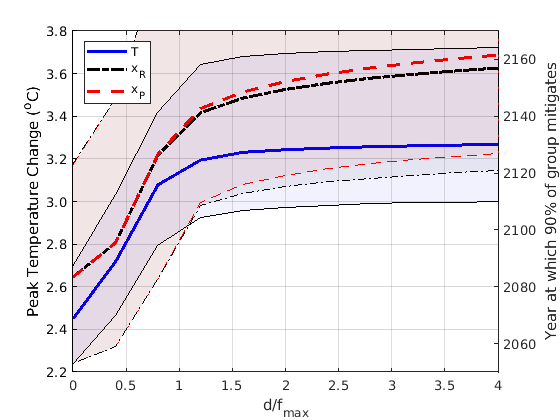

hold on
fill( [v1vals./5 fliplr(v1vals./5)],  [highTvals fliplr(lowTvals)], 'b'); alpha(0.05)
ylabel("Peak Temperature Change (^oC)")
ytickformat('%,.1f')
yyaxis right
%ytickformat('%,.1f')
ylim([2050,2170])
ylabel("Year at which 90% of group mitigates")
p_xR=plot(v1vals./5, t0p9xR_med,'LineWidth',2.25, 'Color','black', 'LineStyle', '-.');
p_xP=plot(v1vals./5, t0p9xP_med,'LineWidth',2.25, 'Color','red', 'LineStyle', '--');
fill( [v1vals./5 fliplr(v1vals./5)],  [t0p9xP_high fliplr(t0p9xP_low)], 'red', 'LineStyle', '--','EdgeColor',"red"); alpha(0.05)
h2 = fill( [v1vals./5 fliplr(v1vals./5)],  [t0p9xR_high fliplr(t0p9xR_low)],'black', 'LineStyle', '-.'); alpha(0.05)

ax=gca;ax.XGrid='on';ax.YGrid='on';
xlabel("d/f_{max}");
ax.YColor = [0.15,0.15,0.15];
yyaxis left
legend([p_T,p_xR,p_xP],["T","x_R","x_P"],'Location', 'northwest')

t_0p8_xR = peakResults.t_0p8_xR;
t_0p8_xP = peakResults.t_0p8_xP;

t0p8xR_med  = median(t_0p8_xR');
t0p8xR_high = quantile(t_0p8_xR',0.95);
t0p8xR_low  = quantile(t_0p8_xR',0.05);

t0p8xP_med  = median(t_0p8_xP');
t0p8xP_high = quantile(t_0p8_xP',0.95);
t0p8xP_low  = quantile(t_0p8_xP',0.05);

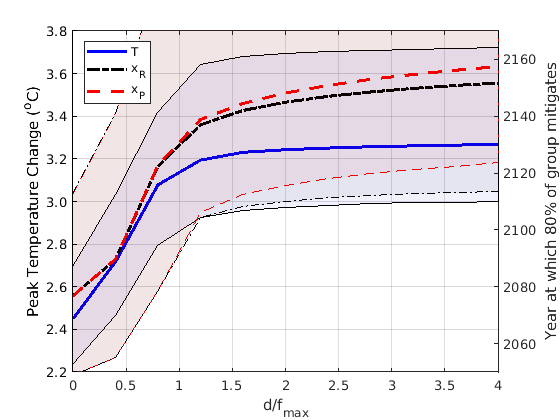

clf
[size_, size_T] = size(peakT);
idx2use=5;
p_T=plot(v1vals./5, Tvals,'LineWidth',2.25, 'Color','blue');
hold on
fill( [v1vals./5 fliplr(v1vals./5)],  [highTvals fliplr(lowTvals)], 'b'); alpha(0.05)
ylabel("Peak Temperature Change (^oC)")
ytickformat('%,.1f')
yyaxis right
%ytickformat('%,.1f')
ylim([2050,2170])
ylabel("Year at which 80% of group mitigates")
p_xR=plot(v1vals./5, t0p8xR_med,'LineWidth',2.25, 'Color','black', 'LineStyle', '-.');
p_xP=plot(v1vals./5, t0p8xP_med,'LineWidth',2.25, 'Color','red', 'LineStyle', '--');
fill( [v1vals./5 fliplr(v1vals./5)],  [t0p8xP_high fliplr(t0p8xP_low)], 'red', 'LineStyle', '--','EdgeColor',"red"); alpha(0.05)
h2 = fill( [v1vals./5 fliplr(v1vals./5)],  [t0p8xR_high fliplr(t0p8xR_low)],'black', 'LineStyle', '-.'); alpha(0.05)

ax=gca;ax.XGrid='on';ax.YGrid='on';
xlabel("d/f_{max}");
ax.YColor = [0.15,0.15,0.15];
yyaxis left
legend([p_T,p_xR,p_xP],["T","x_R","x_P"],'Location', 'northwest')

% 0.6

t_0p6_xR = peakResults.t_0p6_xR;
t_0p6_xP = peakResults.t_0p6_xP;

t0p6xR_med  = median(t_0p6_xR');
t0p6xR_high = quantile(t_0p6_xR',0.95);
t0p6xR_low  = quantile(t_0p6_xR',0.05);

t0p6xP_med  = median(t_0p6_xP');
t0p6xP_high = quantile(t_0p6_xP',0.95);
t0p6xP_low  = quantile(t_0p6_xP',0.05);

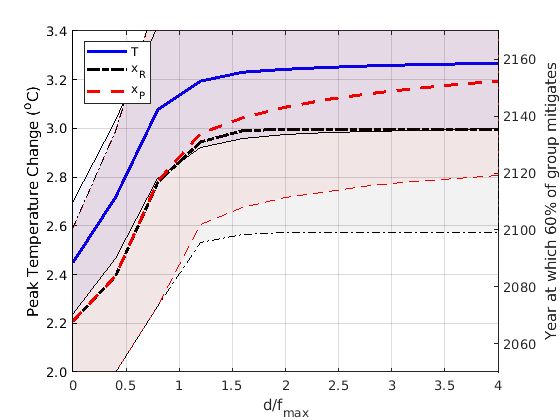

clf
[size_, size_T] = size(peakT);
idx2use=5;
p_T=plot(v1vals./5, Tvals,'LineWidth',2.25, 'Color','blue');
hold on
fill( [v1vals./5 fliplr(v1vals./5)],  [highTvals fliplr(lowTvals)], 'b'); alpha(0.05)
ylabel("Peak Temperature Change (^oC)")
ytickformat('%,.1f')
ylim([2,3.4])
yyaxis right
%ytickformat('%,.1f')
ylim([2050,2170])
ylabel("Year at which 60% of group mitigates")
p_xR=plot(v1vals./5, t0p6xR_med,'LineWidth',2.25, 'Color','black', 'LineStyle', '-.');
p_xP=plot(v1vals./5, t0p6xP_med,'LineWidth',2.25, 'Color','red', 'LineStyle', '--');
fill( [v1vals./5 fliplr(v1vals./5)],  [t0p6xP_high fliplr(t0p6xP_low)], 'red', 'LineStyle', '--','EdgeColor',"red"); alpha(0.05)
h2 = fill( [v1vals./5 fliplr(v1vals./5)],  [t0p6xR_high fliplr(t0p6xR_low)],'black', 'LineStyle', '-.'); alpha(0.05)

ax=gca;ax.XGrid='on';ax.YGrid='on';
xlabel("d/f_{max}");
ax.YColor = [0.15,0.15,0.15];
yyaxis left
legend([p_T,p_xR,p_xP],["T","x_R","x_P"],'Location', 'northwest')